Функция активации нейрона. Сигмоида.

Это одна из S-образной функции, возбуждающая нейрон.

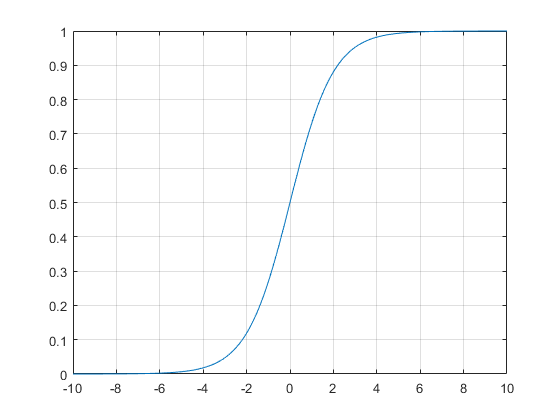


x = [-10:1/100:10];
y = 1./(1+exp(-x));

plot(x,y); grid on;

Еще одна функция активации - обратное значение гиперболического тангенса

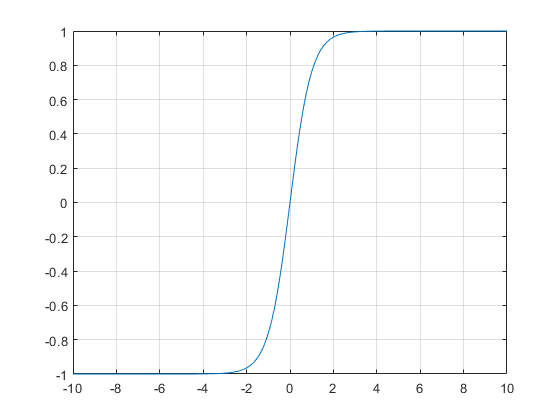

x = [-10:1/100:10];
y = tanh(x);

plot(x,y); grid on;

Расчет простой нейронной сети с 3 слоями с 3 узлами с каждом слое

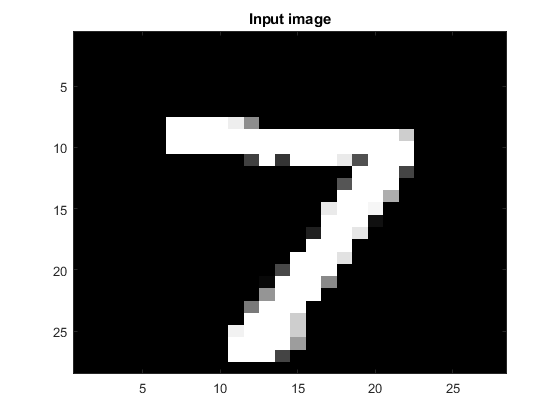

res =     0.0397
    0.0133
    0.0168
    0.0338
    0.0165
    0.0550
    0.0045
    0.8491
    0.0825
    0.0186


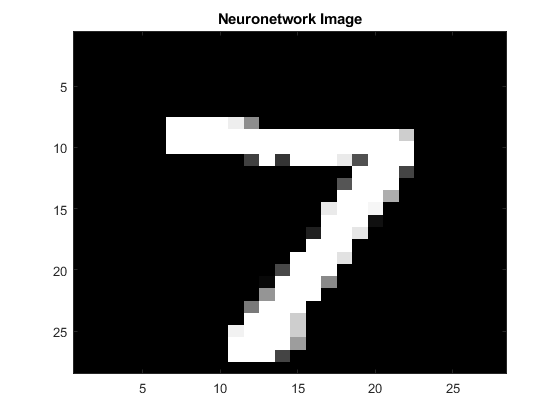

I = [0.9; 0.1; 0.8]  % Входы в Нейросеть

W_input_hidden = [[0.9; 0.2; 0.1;] [0.3; 0.8; 0.5] [0.4; 0.2; 0.6]] % Весовые коэффициенты для скрытого (внутреннего слоя) сети

W_output_hidden = [[0.3; 0.6; 0.8] [0.7; 0.5; 0.1] [0.5; 0.2; 0.9]] % Весовые коэффициенты с выхода скрытого словя сети

X_hidden = W_input_hidden*I % Результат нейронов первого слоя (выходы первого словя неронной сети)

O_hidden = sigmoida(X_hidden) % Применение функции активации нейрона для данных, поступивших с выхода 1-го слоя

X_output = W_output_hidden*O_hidden % Результат нейронов выходного(последнего) слоя

O = sigmoida(X_output) % Применение функции активации на данные, поступившие с выходного(последнего) слоя